# **Introduction**

The Model Reference Adaptive Control (**MRAC**) block computes control actions to make an uncertain controlled system track the behavior of a given reference plant model. It estimates the feedback and feedforward controller gains based on the real-time tracking error between the states of the reference plant model and the controlled system. It incorporates a reference model to capture the desired closed-loop responses and designs the control law and adaptation algorithm to force the output of the plant to follow the output of the reference model.    

### **Model-Reference Adaptive Control (MRAC)**  

This exercise is focused on the design of adaptive control design problem in the** MRAC** scheme for **aero-dynamics** the hovering helicopter in the pitch motion to verification of the designed control system in the Matlab-Simulink environment. The adjustment rules derived upon the **Lyapunov stability** analysis which guarantees boundedness and asymptotic convergence of the model-following error in the MRAC control system.  

### **Plant Description **

              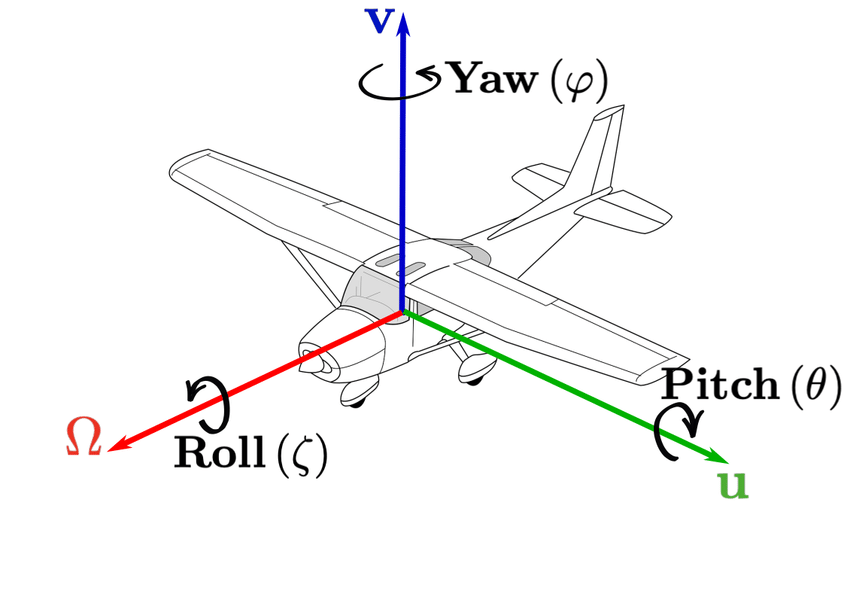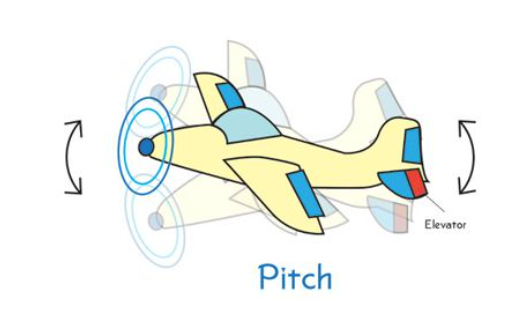

Source: [Yaw Pitch Roll - SadhikaMaja](https://sadhikamaja.blogspot.com/2022/12/yaw-pitch-roll.html) 

Fig 1. Yaw, pitch and roll motion of aero  

The dynamics of pitch motion can be approximated in the following equation:


$$\( \dot{x}(t)=\underbrace{\theta_{a 0}}_{a_{0}} x(t)+\underbrace{(-1)}_{\bar{b}_{0}} \cdot \underbrace{\theta_{b 0}}_{\lambda_{0}}(u(t)+\underbrace{\frac{-\theta_{c 0}}{\theta_{b 0}}}_{\theta_{0}} \underbrace{\left(\frac{360}{\pi} x(t)\right)}_{\phi(x(t))}) \)$$


where

***q=*** pitch rate in rad/s, 

***u*** is the control input in rad, while ***θa*****0**, ***θb*****0**,and ***θc*****0** represent the unknown (**true**) parameters of the pitch dynamics. 

.

# **Control Method and Description**

                                           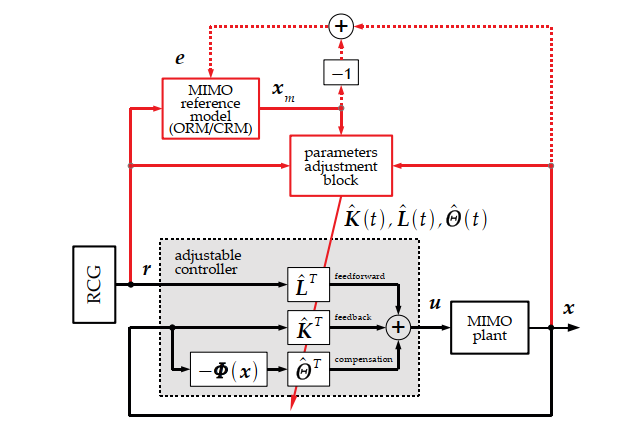

                                                                                          Fig 2a. source: lecture material   

### **Working Principle **

The **working principle** of Model Reference Adaptive Control (MRAC) system:

- The reference model’s desired output is compared to the plant’s actual output. This difference is called the error signal.

- The adjustable controller uses the error signal to generate a control signal that’s sent to the plant.

- The plant’s actual output is fed back to the controller and compared to the reference model’s output. This creates a new error signal.

- The parameter adjustment block uses the error signal to adjust the parameters of the adjustable controller. The goal is to drive the error signal to zero, which means the plant’s output matches the reference model’s output.

### **Control performance requirements**  

- **R1.** pitch rate ***q*****(*****t*****)** follows a time-varying reference in the form of a bounded time-varying signal with bounded time-derivative.

- **R2.** The following **erro**r asymptotically converges to **zero** as time goes infinitive.

# **Control System Design of MRAC**  

The adjustable (adaptive) version of the controller  


$$\( u(t) \triangleq \hat{k}(t) x(t)+\hat{l}(t) r(t)-\hat{\theta}(t) \phi(x(t)) \)$$


where $ \hat{k}(t), \hat{l}(t), \hat{\theta}(t)$ adjusted online in a way that guarantees that the error asymptotically converges to **zero** as time goes infinity.

The *adjustment rules *shall be formulated as follows  


$$\( \ \hat{k}(t)  =\hat{k}(0)-\frac{p b_{0}}{\gamma_{x}} \int_{0}^{t} x(\tau) e(\tau) d \tau \\ 
\hat{l}(t)  =\hat{l}(0)-\frac{p \bar{b}_{0}}{\gamma_{r}} \int_{0}^{t} r(\tau) e(\tau) d \tau, \\
 \hat{\theta}(t)  =\hat{\theta}(0)+\frac{p \bar{b}_{0}}{\gamma_{\phi}} \int_{0}^{t} \phi(x(\tau)) e(\tau) d \tau\end{aligned} \)$$


#               Simulation Result and Analysis 

# 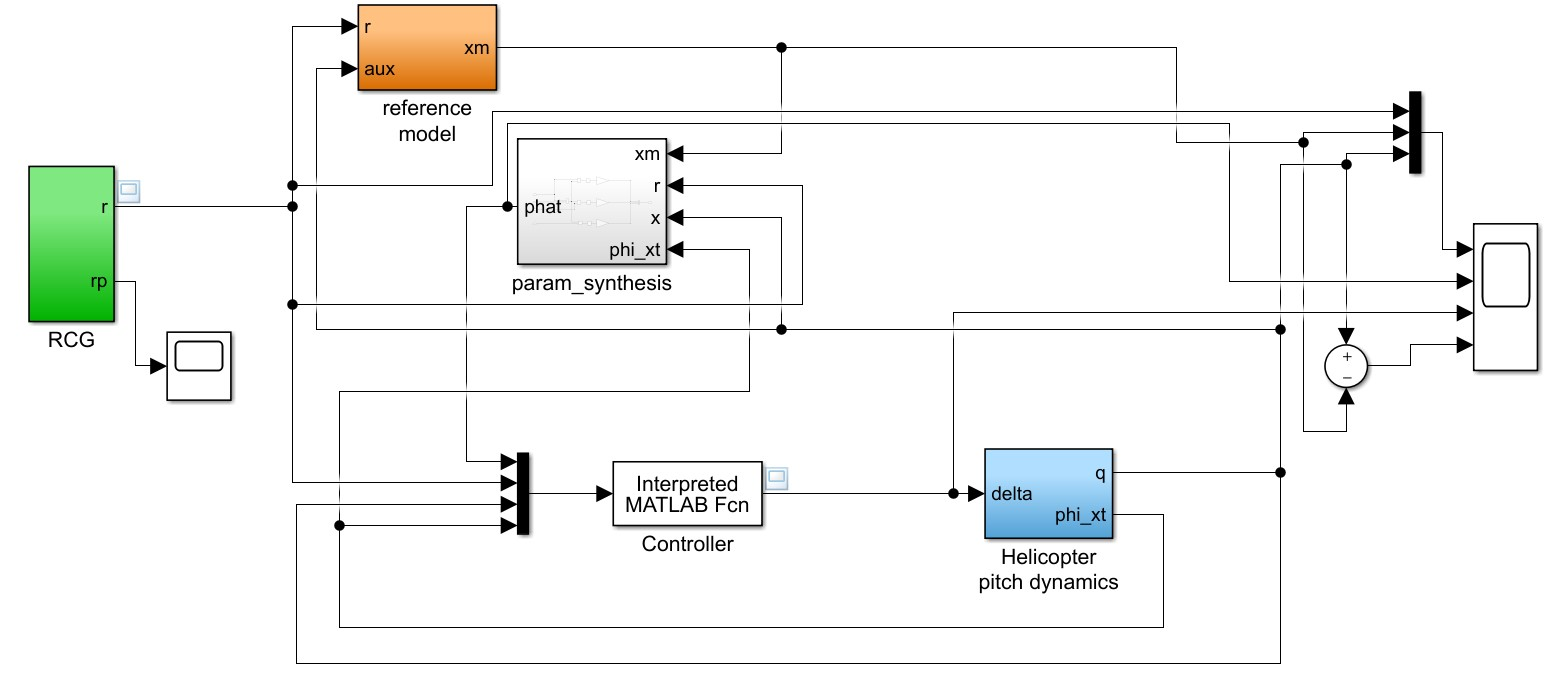    

Fig 2b. Simulink model 

#                           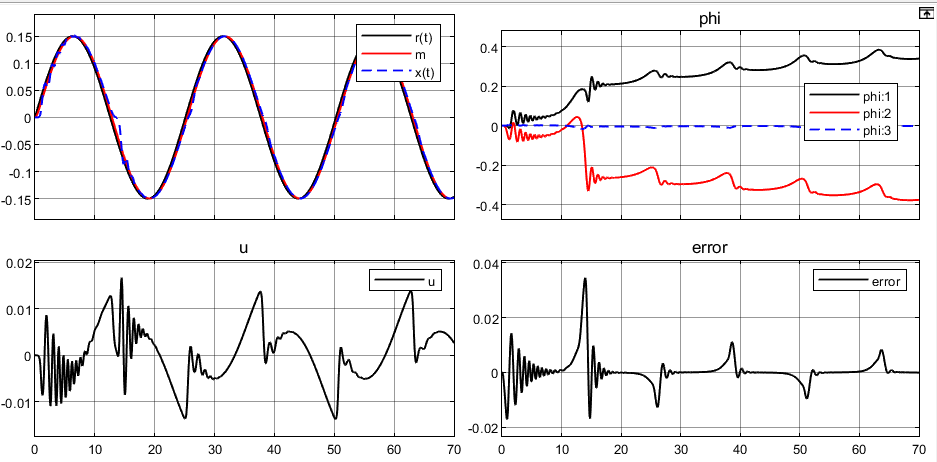

                                 Fig 3. Closed loop adaptation at sigma2e=0 for sinusoidal wave reference input 

                                          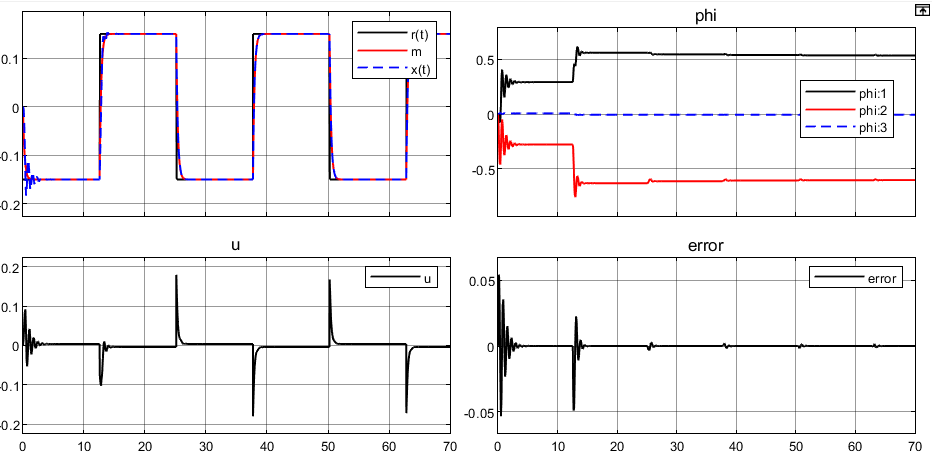

                                                                  Fig 4. Closed loop adaptation at sigma2e=0 with rectangular reference

                                        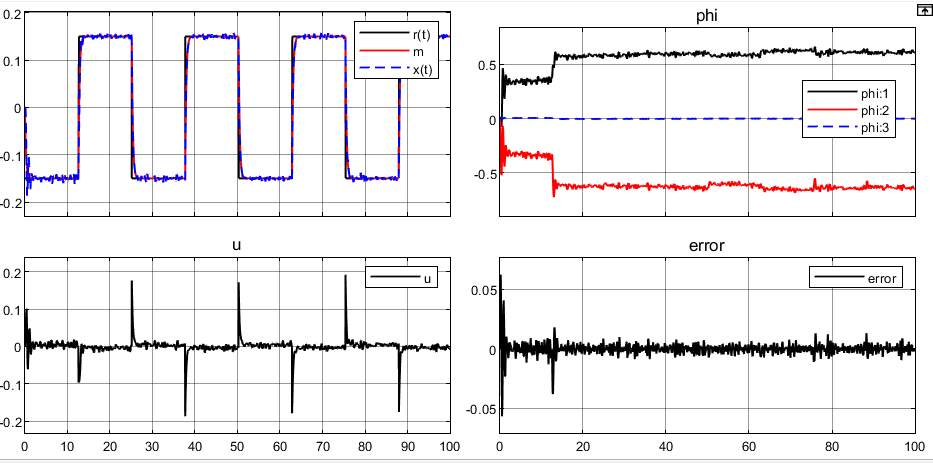

                                                                   Fig 5. Closed loop adaptation at sigma2e=0.001 with rectangular reference input 

                                      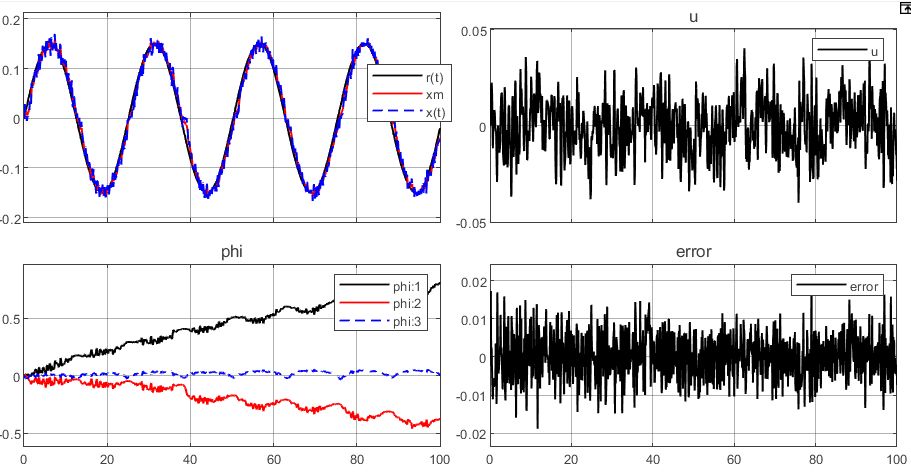

                                Fig 6 a. Closed loop adaptation at sigma2e=0.01 with sinusoidal wave reference input

                                     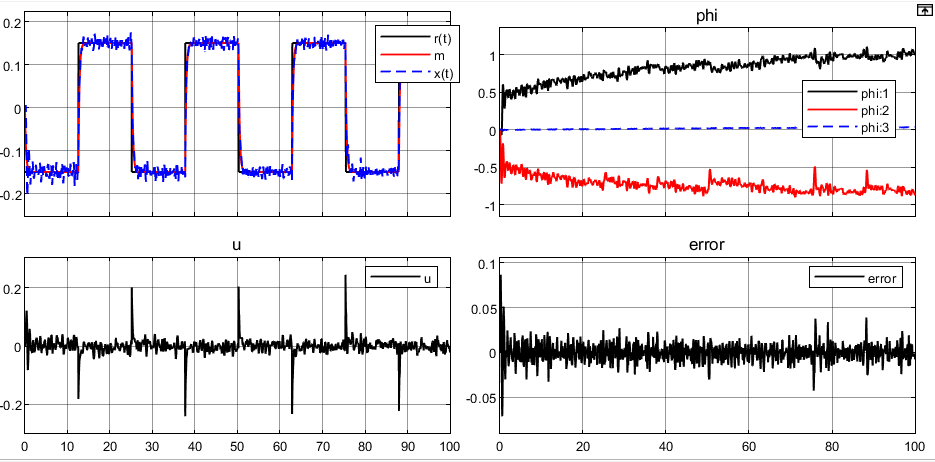

                              Fig 6 b. Closed loop adaptation at sigma2e=0.01 with rectangular reference input 

When the variance of stochastic noise was zero, the transient error was high at the beginning but the error decrease when times went to infinitive as shown in **Figure 3**.

 We used both **rectangular** and **sinuosoidal** reference input , and we observed that** rectangular** wave has rapid transitions from high to low states. These fast changes require the system to rapidly adjust its output to fit the reference, it might be unable to precisely follow these quick changes, resulted in increased error during transitions as shownin **Figure 4** . 

However, the sinusoidal wave is continuous and smooth. The controller has more time to adjust its output to track the reference signal's gradual changes. This resulted in a lower error compared to a rectangular waveas ahown in **Figure 3**. 

When the variance for stochastic noise increased from 0 to 0.01, the noise added uncertainty to the system's behavior, which made it difficult for the controller to distinguish between the actual system output and the effect of noise. 

This led to a larger error between the system output and the desired reference model output as shown in **Figure 6.b **as compared to the error free.

The system satisfy performance requirements of R1 and R2 in all the cases.

##                                                   **With addition of auxilary feedback signal** 

                                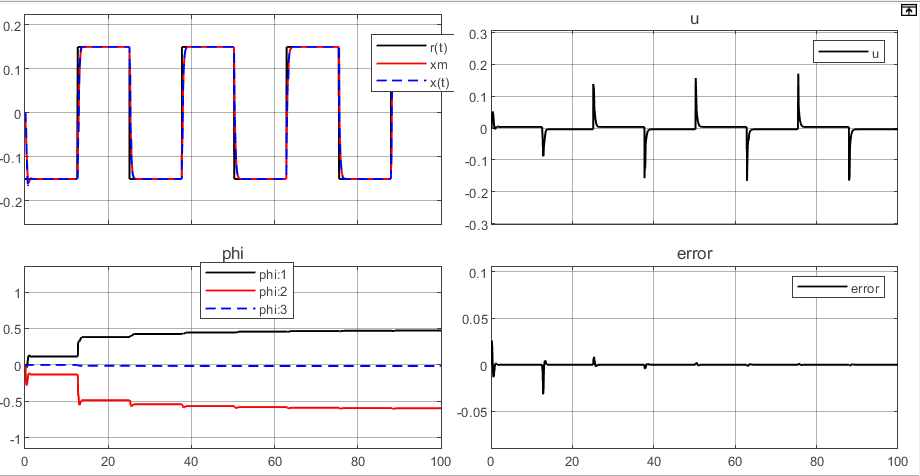

                                                  Fig 7. Closed loop adaptation at sigma2e=0.0 with rectangular reference input 

                                    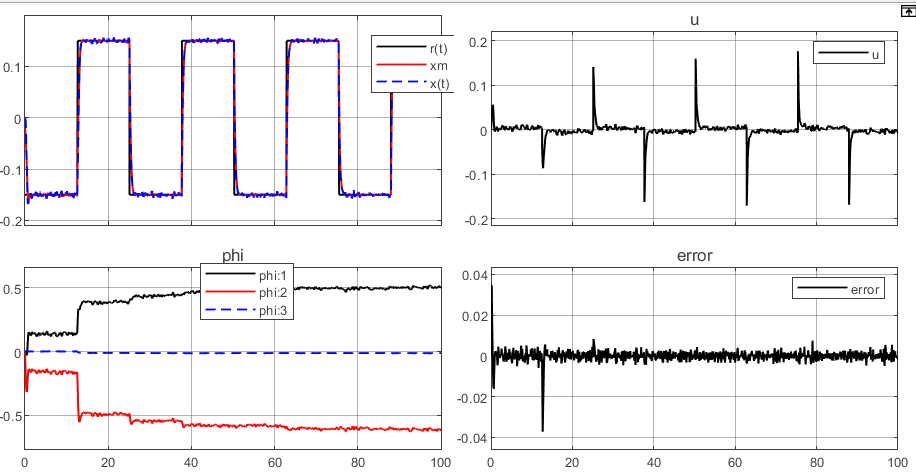

                                                                     Fig 8.  Closed loop adaptation at sigma2e=0.001 with rectangular reference input 

                                       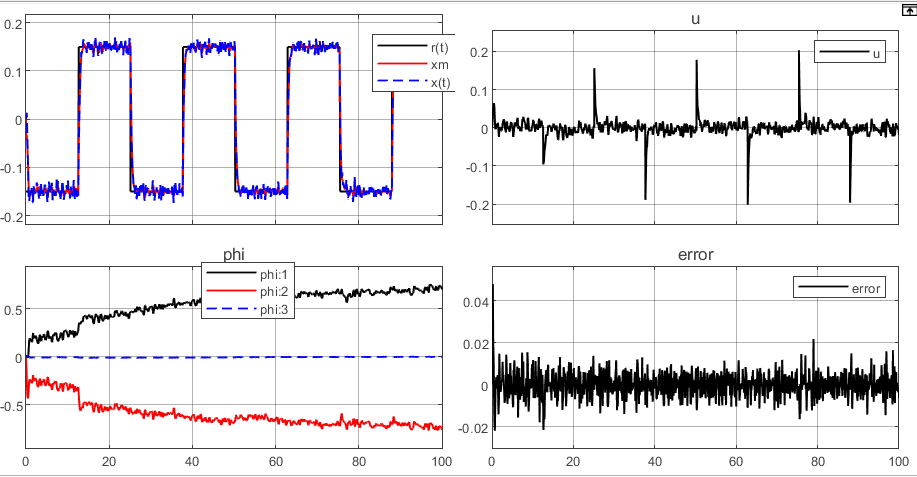

                                                      Fig 9.  Closed loop adaptation at sigma2e=0.01 with rectangular reference input 

When we introduced th auxilary feed back signal,  the adaptation process was faster and the transient response was less disturbed as we compared to the result we got with out the addition auxilary feed back signal.

 When the variance for stochastic noise increased from 0 to 0.01, the noise added uncertainty to the system's behavior, which made it difficult for the controller to distinguish between the actual system output and the effect of noise. 

This led to a larger error between the system output and the desired reference model output as shown in **Figure 9 **as compared to the error free.

The system satisfy performance requirements of R1 and R2 in all the cases.

## **Checking the effect of some parameter changes on the plant**

### **Condition 1: Changing the adaptation gains gamma_x, gamma_r, gamma_phi**

In Model Reference Adaptive Control (**MRAC**), the adaptation gain determines how quickly and effectively the controller learns and adjusts according to the desired behavior of the reference model.

From this simulation we checked both condition

- **For Higher Adaptation Gain:** 

When we used gamma_x, gamma_y and gamma_phi half of the given value, we observed that  the adaptive controller quickly changed the parameters in response to the error (**x-xm**). It showed faster convergence, which means that the output of the plant (**x**) tracked the reference model output(**xm**) more quickly. However, when we decreased the value of adatation gains, it led to instability in the output of the system and made the control signal noisy, this decreased the control performance as shown in **Fig 11**.

                          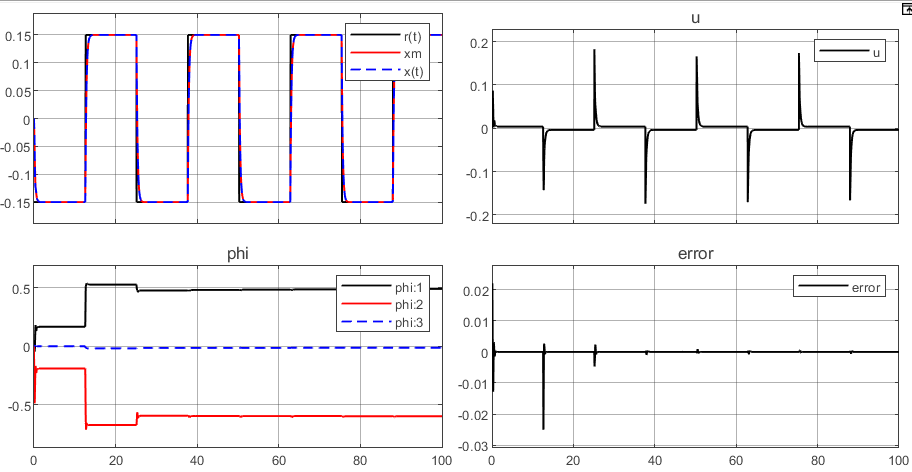

                             Fig 10. Adaptation gain half times the given adaptation gain (eg. gamma_x_new= gamma_x_old/2)

                                   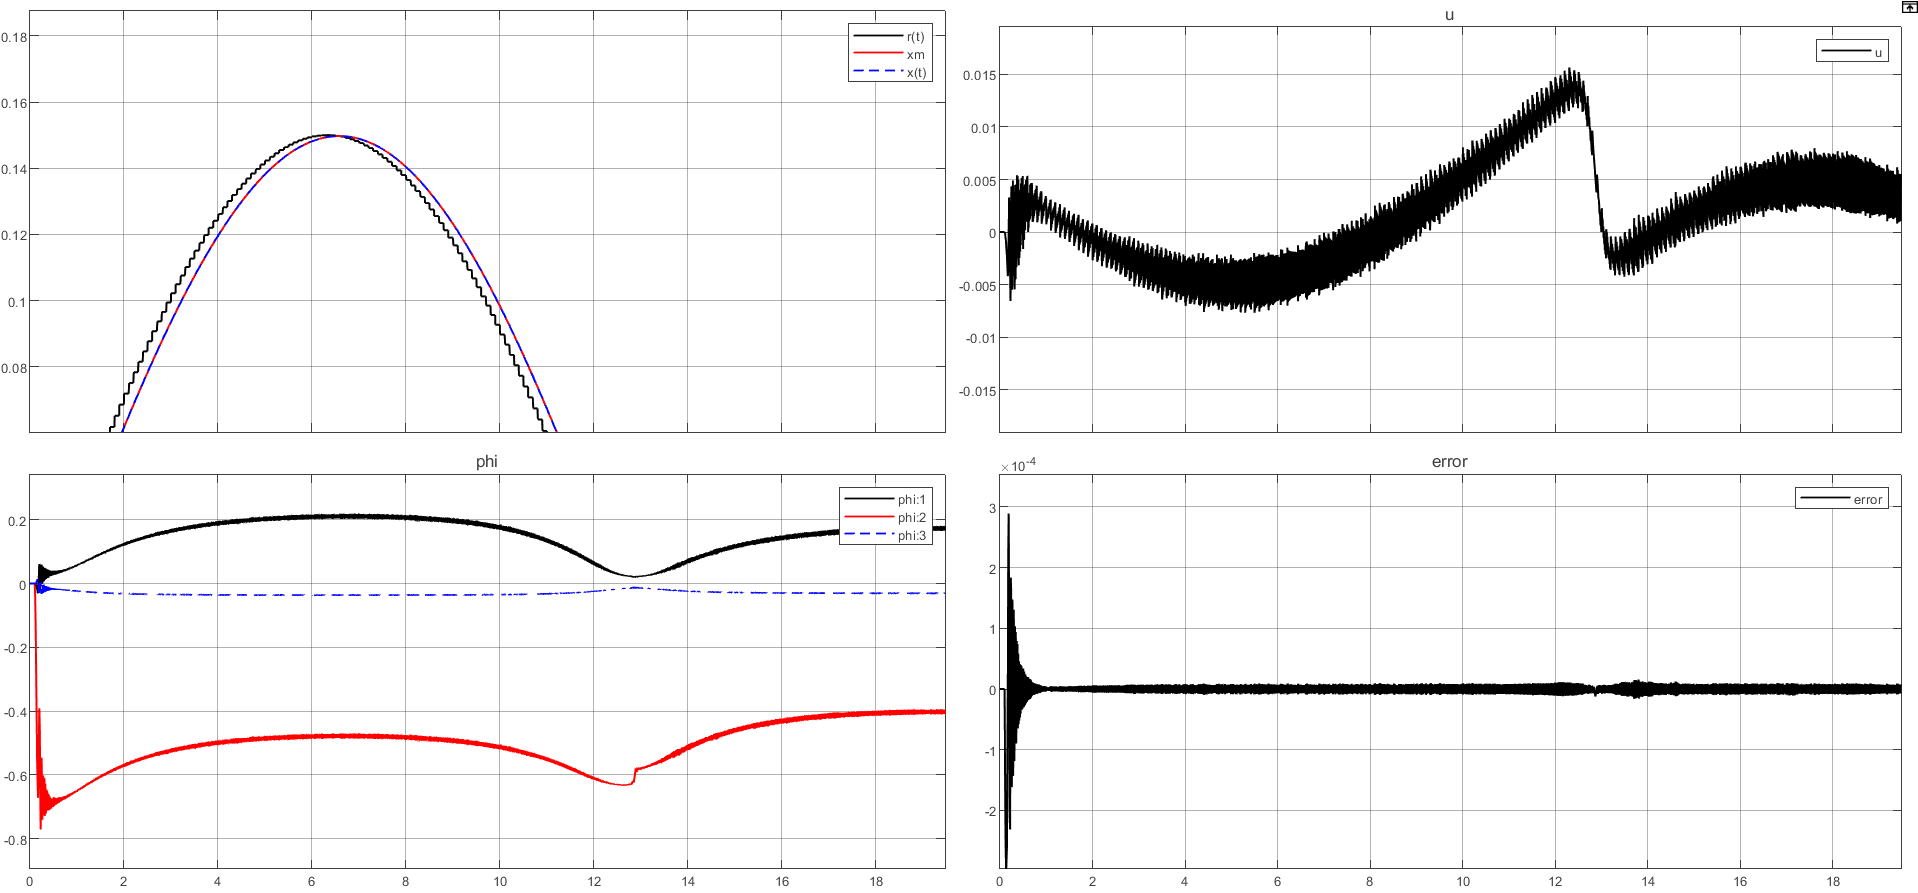

                              Fig 11. Adaptation gain one-fifth times the given adaptation gain (eg. gamma_x_new= gamma_x_old/5)

**2. For Lower Adaptation Gain:** 

We used a 5 times lower adaptation gain than the given one, which makes the adaptation process slower since the controller makes smaller adjustments with each iteration. It might take longer for the system's output to converge and accurately track the reference model. 

### **Condition 2: Changing value of reference model parameters am and bm**

The values of **am** and** bm** influence on the convergence and tracking of our system. Appropriate values (in this experiment, i.e., am = -4 and bm = 4) help the controller adjust its internal parameters in a way that reduces the error between the system output and the reference model output. This leads to better tracking performance, where the system output converges closer to the desired behavior represented by the reference model, as shown in figures three and four. 

The effect of improper values of the parameters am and bm

**Low values of the parameters am and bm**

We used four times less value than the given value. As shown in Figure 12, the adaptation process was slow, resulting in low tracking performance.

**High values of the parameters am and bm**

when we used a higher value than the given value. The performance of the controller was not good.

However, improper values for am and bm reduce the adaptation process.         

                                    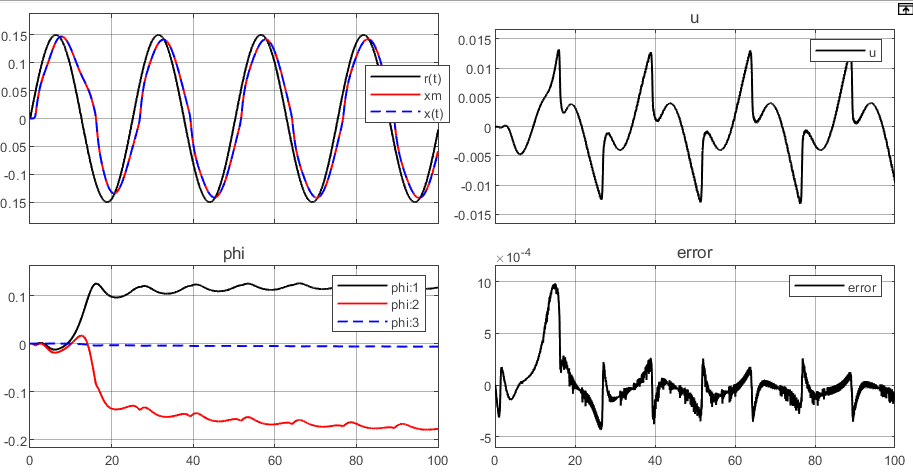

                                        Fig 12. The effect low values of  parameter am and bm

### **Condition 3: Adding auxiliary feedback gain ke**

In classical reference models (with out auxilary feed back signal), the model doesn't account for uncertainties or disturbances in the actual system. 

From  **figure 3**, we observed that,  the adaptation process was slower and the transient response was higly disturbed as we compared to the result we got with the addition auxilary feed back signal.

**Introduction of auxilary signal (ke):** 

The introduction of an auxiliary feedback signal (ke) helps the reference model itself adapt to the actual system's behavior and allows the control system to perform better in situations with uncertainties or disturbances since it gives information about the error between the actual system's output and the desired output from the reference model. 

With the introduction of the auxilary feed-back signal, the adaptation process was faster, and the transient response of the system was less disturbed as compared to the classical case. However, a high-value auxilary feedback signal leds to high disturbances at the initial stage(the transient response was highly disturebed), but the steady state response was good, as shown in **Figure 13.** 

                                         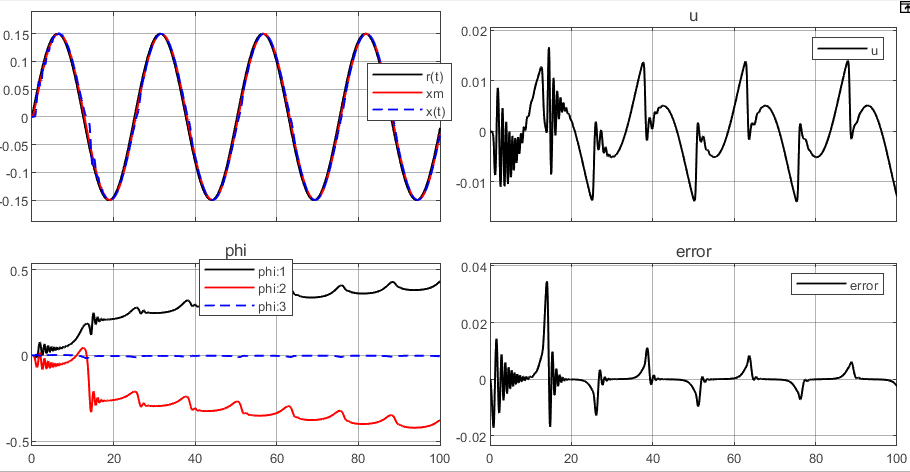

                                                    Fig 13. The effect of high auxilary feed back signal 

# Conclusion

From this experiment, we conclude that: 

- The appropriate value of **adaptation gain** is important to ensure good control performance, good tracking, and stability.

- Proper values of adaptive Parameters (am, bm) ensure good tracking and stability. 

- Higher noise variance increases tracking error, slows convergence, and requires more control effort.

- Lower noise leads to good control performance and tracking.

- The system satisfy performance requirements of R1 and R2 in all the cases.

# Appendix 

inti

clearvars;
clc;
global  R wr Tc am bm gammax gammar gammaphi khat0 lhat0 thetahat0 bbar
Tc = 0.1;
sigma2e = 0.01;
am =-4.0;
bm = 4.0;
R = 0.15;
wr = 0.25;
bbar = -1;
gammax = 0.0005;
gammar = 0.0005;
gammaphi = 0.1;
p = -1/(2*am)
khat0 = 0;
lhat0 = 0; 
thetahat0 = 0;
ke = 10; 

Mraccontroller

function out = Mraccontroller(in)
r = in(1);
phi = in(2:4)
q = in(5)

delta = phi(1)*q+phi(2)*r-phi(3)*tanh((360/pi)*q)

out = delta; 

                         **Phi  (**the *adjustment rules*  )       

                       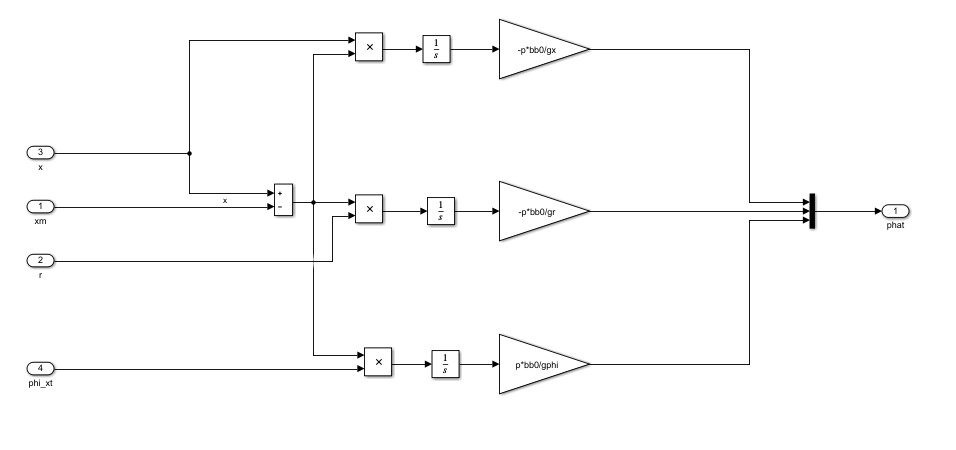

**Plant model**

                                       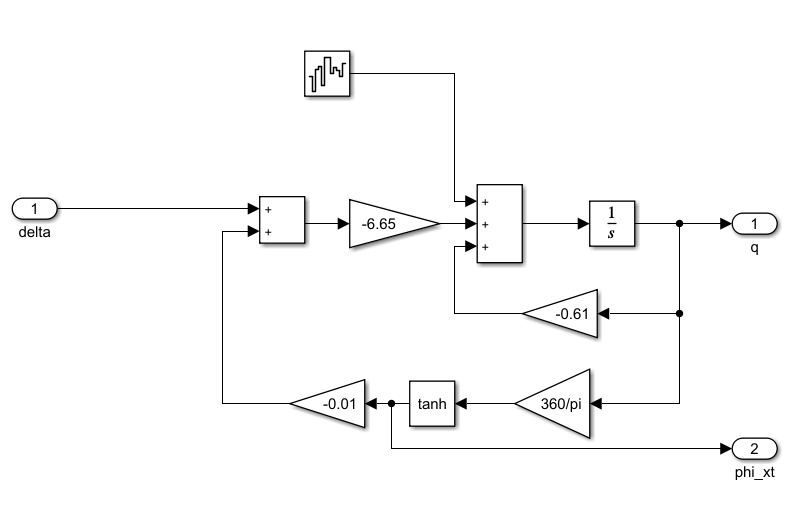

**Reference Model                                                                                                               **

              **Reference input**